# Dominance based resource sharing

Num_individuals=100;
Num_time_steps=120;
nut_init=50;
m_for=1;
m_nur=1;
mu=50;
nutrition_levels = nut_init*(0.9 + 0.2*rand(Num_individuals,1));

%In our simulation, nursing will be denoted by 1, and foraging by 2
worker_roles = ones(Num_individuals,Num_time_steps); %Initially workers all nurse until they are stimulated to go forage
food = 0; %Initialising no food available
food_share=zeros(Num_individuals, 1);
R=4; %Amount of food collected by each forager
num_foragers=zeros(1,Num_time_steps); %Initialising number of foraagers

dom_vals= [0.9*ones(1,60), 0.2*ones(1,40)];
Sk = exp(dom_vals)./(sum(exp(dom_vals))); 

ans = 1.0000

Sk =     0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125


ans =     2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034    2.0034


nutrition_levels =   162.2674
  160.6265
  159.6380
  162.4861
  155.8537
  162.6665
  159.5093
  155.9920
  163.4955
  164.3723


num_foragers =     50    62    45    31    28    23    22    24    26    25    26    29    35    35    36    36    34    36    39    38    38    38    38    39    39    39    40    37    39    39    39    38    38    39    38    40    39    40    39    40    40    40    38    39    40    40    39    39    40    39


worker_roles =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1    

repetitions =      0
    88
    78
    74
    90
    98
    94
    95
    97
    95


q =          0
    0.8800
    0.7800
    0.7400
    0.9000
    0.9800
    0.9400
    0.9500
    0.9700
    0.9500


p1 =     0.6400    0.7400    0.5400    0.2800    0.2000    0.2000    0.2600    0.2700    0.2800    0.3100    0.3100    0.3200    0.3300    0.3300    0.3500    0.3400    0.3500    0.3600    0.3600    0.3600    0.3500    0.3500    0.3800    0.3800    0.3700    0.3700    0.3700    0.3800    0.3800    0.3800    0.3900    0.3700    0.3800    0.3900    0.3900    0.3800    0.3800    0.4000    0.3800    0.3900    0.4000    0.4000    0.4000    0.4000    0.3900    0.3900    0.4000    0.4000    0.3900    0.3900


p2 =     0.3600    0.2600    0.4600    0.7200    0.8000    0.8000    0.7400    0.7300    0.7200    0.6900    0.6900    0.6800    0.6700    0.6700    0.6500    0.6600    0.6500    0.6400    0.6400    0.6400    0.6500    0.6500    0.6200    0.6200    0.6300    0.6300    0.6300    0.6200    0.6200    0.6200    0.6100    0.6300    0.6200    0.6100    0.6100    0.6200    0.6200    0.6000    0.6200    0.6100    0.6000    0.6000    0.6000    0.6000    0.6100    0.6100    0.6000    0.6000    0.6100    0.6100


D =    -1.0000    0.4304    0.5501    0.2399    0.3235    0.4412    0.5280    0.5682    0.6253    0.6603    0.7127    0.7174    0.7390    0.7928    0.7982    0.7961    0.8165    0.8361    0.8175    0.8175    0.7798    0.7982    0.7965    0.8911    0.8172    0.7984    0.8359    0.8722    0.8911    0.8533    0.8886    0.8359    0.8722    0.8886    0.8695    0.8722    0.8911    0.8846    0.8533    0.8886    0.9038    0.9231    0.9231    0.9231    0.8886    0.9077    0.9038    0.9231    0.8886    0.8695


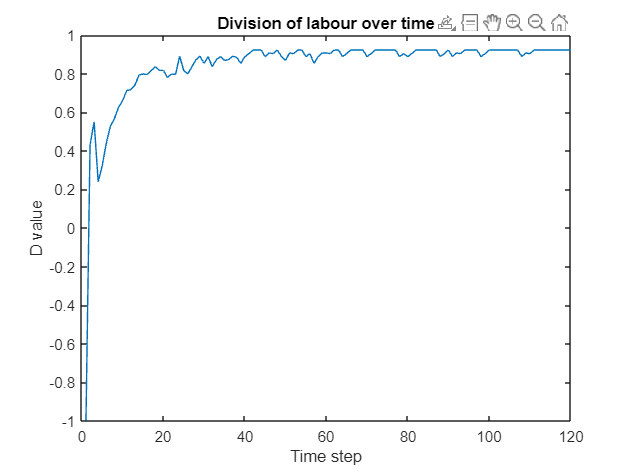


for time = 1:Num_time_steps
    for worker = 1:Num_individuals
        perception_err = -1+ 2*rand(); %Error with which they perceive their own hunger
        if nutrition_levels(worker) + perception_err<= mu
            worker_roles(worker,time) = 2;
        else
            worker_roles(worker,time)=1;
        end

        if worker_roles(worker,time)==1
            nutrition_levels(worker) =nutrition_levels(worker)-m_nur+ food_share(worker);
        else %if the role was 2
            nutrition_levels(worker) = nutrition_levels(worker)-m_for+ food_share(worker);
        end

    end


        num_foragers(1,time) = sum(worker_roles(:,time)==2);
        food = R*num_foragers(1,time);
        food_share=Sk.*food;
end

## Number of nursers and foragers over time plot

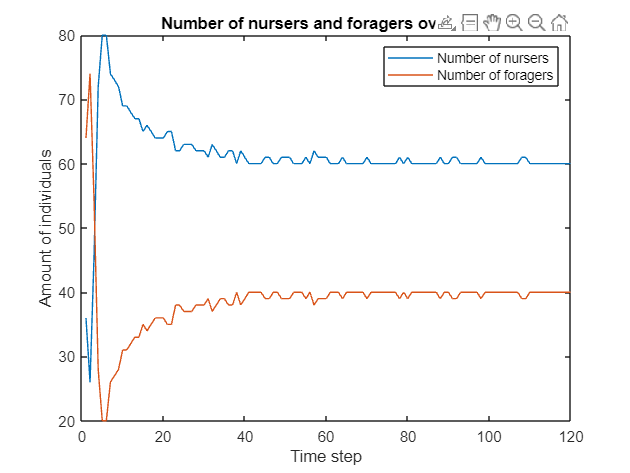

plot(100-num_foragers)
hold on
plot(num_foragers)
hold off
title('Number of nursers and foragers over time')
ylabel('Amount of individuals')
xlabel('Time step')
legend('Number of nursers', 'Number of foragers')

## Nutrition levels of the nursers and foragers plot

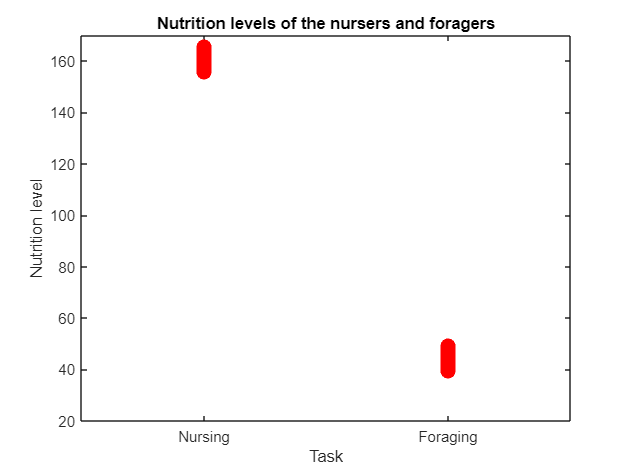

x = worker_roles(:,120);
x_categorical = categorical(x, [1 2], {'Nursing', 'Foraging'});

plot(x_categorical, nutrition_levels, 'r.', 'MarkerSize', 30)
xlabel('Task')
ylabel('Nutrition level')
ylim([20, 170])
title('Nutrition levels of the nursers and foragers')

## Calculation of division of labour

repetitions = zeros(120,1);

for j = 2:120
    for i=1:100
        %if Worker_tasks(i,j) ~= 0
           if worker_roles(i,j)==worker_roles(i,j-1)
                 repetitions(j)=repetitions(j)+1;
           end
        %end
    end
end

repetitions

q = repetitions/Num_individuals
p1 = num_foragers./Num_individuals
p2 = (100-num_foragers)./Num_individuals

D = [];

for i =1:length(q)
    D(i) = q(i)./(p1(i).^2 + p2(i).^2) - 1;
end

## Division of labour over time plot

plot(1:Num_time_steps, D)
title('Division of labour over time')
ylabel('D value')
xlabel('Time step')

## Dominance values plot

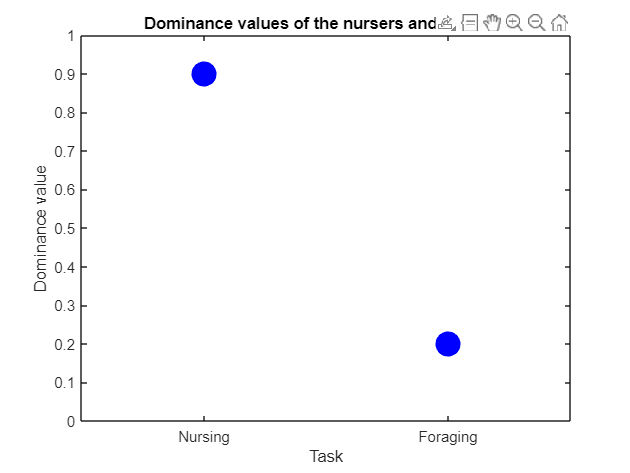

plot(x_categorical, dom_vals, 'b.', 'MarkerSize', 50 )
xlabel('Task')
ylabel('Dominance value')
ylim([0 1])
title('Dominance values of the nursers and foragers')

%plot(Sk, worker_roles(:,120) 'ro')
